## ECE 537 : Assignment 3

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;

%dimensions
K = 1000;
D = 3;

%mean
mu_A = [0 4 7];
mu_B = [10 5 5];
mu_C = [-2 -5 -5];

%covariance
sigma_A = [6.5000 2.1651 1.2500 ; 2.1651 5.1250 2.3816;1.2500 2.3816 2.3750];
sigma_B = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456 ;-1.4481 -0.6456 1.2880];
sigma_C = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];

%data
data_A = gaussian_data(K,D,mu_A,sigma_A);
data_B = gaussian_data(K,D,mu_B,sigma_B);
data_C = gaussian_data(K,D,mu_C,sigma_C);

Npt = 200;
%3d volume of regular grid points
V = vol3D([-15 20 -15 20 -15 20],Npt);
%priori probabilities 
pwA = 0.3;
pwB = 0.3;
pwC = 0.3;

%likelihood
pxwA = gaussian_density(mu_A,sigma_A,V);
pxwB = gaussian_density(mu_B,sigma_B,V);
pxwC = gaussian_density(mu_C,sigma_C,V);

%evidence
px = pxwA*pwA + pxwB*pwB + pxwC*pwC; %evidence

%bayes theorem for posteriori
pwAx = (pxwA*pwA)./px;
pwBx = (pxwB*pwB)./px;
pwCx = (pxwC*pwC)./px;

**Task 1: **Use Matlab's neural network tool box to create a 3 class decision classifier for the 3 class data generated in Exercise 1.

Solution: 

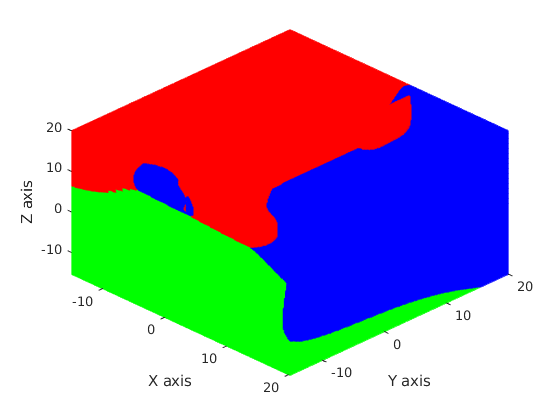

ans =   Axes with properties:

             XLim: [-15 20]
             YLim: [-15 20]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


data = [data_A;data_B;data_C]; %total data
target = [ones(1000,1);2*ones(1000,1);3*ones(1000,1)]; %corresponding labels
target_new = bsxfun(@eq, target(:), 1:max(target)); %one hot encoder


%neural network classifier
x = data';
t = target_new';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% % Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(V');
%e = gsubtract(t,y);
%performance = perform(net,t,y)
%tind = vec2ind(t);
yind = vec2ind(y);
%percentErrors = sum(tind ~= yind)/numel(tind);
class_index = yind';

visualize_points(class_index,V)

**Task 2: **Plot the decision boundaries created by this trained neural network classifier and discuss the "correctness" of these boundaries versus the Bayesian class boundaries that were generated in Exercise

Solution: The bayes decision boundary provides the optimal solution to the general decision problem due to the known probability structure underlying the categories.

Although the Bayesian rule provides the optimal solution with respect to the classification error probability, its application requires the estimation of the respective conditional PDFs; this is not an easy task once the dimensionality of the feature space assumes relatively large values. This paves the way for considering neural networks.

One may wonder how a performance close to the optimal classifier can be obtained, even in theory and asymptotically, because the Bayesian classifier exploits the statistical information for the data distribution while the neural network does not take into account such information

Neural network try to optimize it so as to minimize the respective empirical loss. The form of non-linearit is learned from the training data.

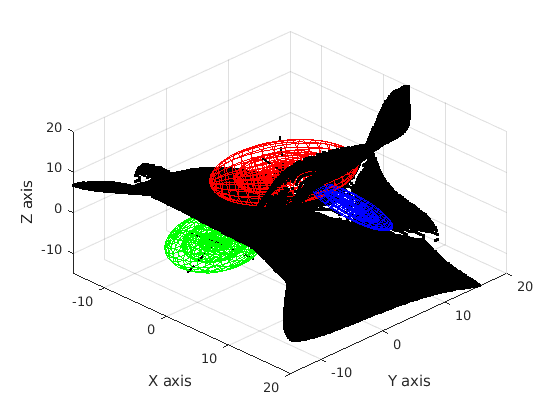

axes_plot =   Axes with properties:

             XLim: [-15 20]
             YLim: [-15 20]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


figure(2);
change_val = zeros(200^3,1);
for i = 1:40000
    change_val((i-1)*200+1 :200*i,:)  = [0; diff(class_index((i-1)*200+1 :200*i))];
end 
b = V(change_val~= 0,:);
axes_plot = visualize_boundary(data_A, data_B, data_C, b)

**Task 4** - Perform 10 different neural network trainings, each using different random seeds, and discuss the variability that arises in the produced interclass decision boundaries. 

• Discuss what would occur relative to the produced decision boundaries if 100 different neural network training were conducted. 

• Discuss which of the resulting neural network decision boundaries is the correct (or more correct) boundary.

 • Discuss how the nature of the neural network decision boundaries would change as increasingly more neurons are added to the neural network’s hidden layer(s). 

% Test Case 1 
NN_Classification_T4_1  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)

Unrecognized function or variable 'input_data'.

change_val_T4_1  = [0; diff(NN_Classification_T4_1)] % Finds points where classification of points in volume changes
b_T4_1 = volume(change_val_T4_1~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_1 = visualize_boundary(data_A, data_B, data_C, b_T4_1);
title('Task 4 - Test Case 1')

% Test Case 2 
NN_Classification_T4_2  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)
change_val_T4_2  = [0; diff(NN_Classification_T4_2)] % Finds points where classification of points in volume changes
b_T4_2 = volume(change_val_T4_2~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_2 = visualize_boundary(data_A, data_B, data_C, b_T4_2);
title('Task 4 - Test Case 2')

% Test Case 3 
NN_Classification_T4_3  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)
change_val_T4_3  = [0; diff(NN_Classification_T4_3)] % Finds points where classification of points in volume changes
b_T4_3 = volume(change_val_T4_3~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_3 = visualize_boundary(data_A, data_B, data_C, b_T4_3);
title('Task 4 - Test Case 3')

% Test Case 4 
NN_Classification_T4_4  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)
change_val_T4_4  = [0; diff(NN_Classification_T4_4)] % Finds points where classification of points in volume changes
b_T4_4 = volume(change_val_T4_4~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_4 = visualize_boundary(data_A, data_B, data_C, b_T4_4);
title('Task 4 - Test Case 4')

% Test Case 5 
NN_Classification_T4_5  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)
change_val_T4_5  = [0; diff(NN_Classification_T4_5)] % Finds points where classification of points in volume changes
b_T4_5 = volume(change_val_T4_5~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_5 = visualize_boundary(data_A, data_B, data_C, b_T4_5);
title('Task 4 - Test Case 5')

% Test Case 6 
NN_Classification_T4_6  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)
change_val_T4_6  = [0; diff(NN_Classification_T4_6)] % Finds points where classification of points in volume changes
b_T4_6 = volume(change_val_T4_6~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_6 = visualize_boundary(data_A, data_B, data_C, b_T4_6);
title('Task 4 - Test Case 6')

% Test Case 7 
NN_Classification_T4_7  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)
change_val_T4_7  = [0; diff(NN_Classification_T4_7)] % Finds points where classification of points in volume changes
b_T4_7 = volume(change_val_T4_7~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_7 = visualize_boundary(data_A, data_B, data_C, b_T4_7);
title('Task 4 - Test Case 7')

% Test Case 8 
NN_Classification_T4_8  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)
change_val_T4_8  = [0; diff(NN_Classification_T4_8)] % Finds points where classification of points in volume changes
b_T4_8 = volume(change_val_T4_8~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_8 = visualize_boundary(data_A, data_B, data_C, b_T4_8);
title('Task 4 - Test Case 8')

% Test Case 9 
NN_Classification_T4_9  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)
change_val_T4_9  = [0; diff(NN_Classification_T4_9)] % Finds points where classification of points in volume changes
b_T4_9 = volume(change_val_T4_9~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_9 = visualize_boundary(data_A, data_B, data_C, b_T4_9);
title('Task 4 - Test Case 9')

% Test Case 10 
NN_Classification_T4_10  = nprtool_fun(input_data, target_new, volume, layers, training_per, testing_per, validation_per)
change_val_T4_10  = [0; diff(NN_Classification_T4_10)] % Finds points where classification of points in volume changes
b_T4_10 = volume(change_val_T4_10~= 0,:) % Subset of volume where points change (describes the decision boundary)
vis_boundary_T4_10 = visualize_boundary(data_A, data_B, data_C, b_T4_10);
title('Task 4 - Test Case 10')

function f = gaussian_data(K,D,mu,sigma)
%function for generating gaussian data
    % generate a subset of samples from normal distribution
    N = randn(K,D);
    % centralize the data at zero-mean
    N_c = N - mean(N);
    % obtain eigen values and eigen vectors for covariance of N
    [v,d] = eig(cov(N_c));
    %generate the whitening transform
    R = v*inv(sqrt(d));
    %apply the whitening transform on the centralized data
    W  = N_c*R;
    %obtain eigen values and eigen vectors for sigma
    [vn,dn] = eig(sigma);
    % generate the inverse whitening transform
    R_inv = sqrt(dn)*inv(vn);
    % apply the inverse whitening transfrom on the whitened gaussian data
    f = W*R_inv;  
    % centralize the data at mu
    f = f + mu;
end 

function NN_classification = nprtool_fun(input_data, target_data, testing_data)
% NPRTOOL generated script 
x = input_data';
t = target_data';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Train the Network
[net,tr] = train(net,x,t);

% % Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)
% tind = vec2ind(t);
% yind = vec2ind(y);
% percentErrors = sum(tind ~= yind)/numel(tind);
% 
% % View the Network
% view(net)
% 
% % Plots
% % Uncomment these lines to enable various plots.
% %figure, plotperform(tr)
% %figure, plottrainstate(tr)
% %figure, ploterrhist(e)
% %figure, plotconfusion(t,y)
% %figure, plotroc(t,y)

%Changes made to generated script to test generated model on volume data
% Test the Network on volume data
y = net(testing_data');
yind = vec2ind(y);
NN_classification = yind';
end

function [x1,y1,z1,x2,y2,z2,x3,y3,z3] = ellipse_cord(data)

    mu = mean(data);
    sigma = cov(data);
    [v,d] = eig(sigma);
    %plot ellipsoid for three standard deviations
    radius = sqrt(diag(d));
    [x1,y1,z1] = ellipsoid(0, 0, 0, radius(1),radius(2),radius(3));
    [x2,y2,z2] = ellipsoid(0, 0, 0, 2*radius(1),2*radius(2),2*radius(3));
    [x3,y3,z3] = ellipsoid(0, 0, 0, 3*radius(1),3*radius(2),3*radius(3));
    

    x1 = kron(v(:,1),x1);y1 = kron(v(:,2),y1);z1 = kron(v(:,3),z1);
    x2 = kron(v(:,1),x2);y2 = kron(v(:,2),y2);z2 = kron(v(:,3),z2);
    x3 = kron(v(:,1),x3);y3 = kron(v(:,2),y3);z3 = kron(v(:,3),z3);
    dat1 = x1 + y1 + z1; dat2 = x2 + y2 + z2 ; dat3 = x3 + y3 + z3; % to account for rotation of all three axis 
    n = size(dat1,2);
    x1 = dat1(1:n,:) + mu(1); y1 = dat1(n+1:2*n,:) + mu(2); z1 = dat1(2*n+1:end,:) + mu(3); 
    x2 = dat2(1:n,:) + mu(1); y2 = dat2(n+1:2*n,:) + mu(2); z2 = dat2(2*n+1:end,:) + mu(3);
    x3 = dat3(1:n,:) + mu(1); y3 = dat3(n+1:2*n,:) + mu(2); z3 = dat3(2*n+1:end,:) + mu(3);
%         [x1,y1,z1] = ellipsoid(mu(1),mu(2),mu(3), radius(1),radius(2),radius(3));
%         [x2,y2,z2] = ellipsoid(mu(1),mu(2),mu(3), 2*radius(1),2*radius(2),radius(3));
%         [x3,y3,z3] = ellipsoid(mu(1),mu(2),mu(3), 3*radius(1),3*radius(2),3*radius(3));

        
end 

function val = gaussian_density(mu,sigma,X)
%finds the gaussian pdf 
    [k,d] = size(X);
    X0 = bsxfun(@minus,X,mu);
    [R,err] = cholcov(sigma,0);
    xRinv = X0 / R;
    % determinant of sigma is product of diagonal elements of cholesky decomposition
    logSqrtDetSigma = sum(log(diag(R))); 
    quadratic = sum(xRinv.^2, 2);
    val = exp(-0.5*quadratic - logSqrtDetSigma - d*log(2*pi)/2);
end 

function axes_plot = visualize_boundary(data_A, data_B, data_C, b)

    mu_A = mean(data_A);
    mu_B = mean(data_B);
    mu_C = mean(data_C);

    sigma_A = cov(data_A);
    sigma_B = cov(data_B);
    sigma_C = cov(data_C);

    [vA,dA] = eig(sigma_A);
    [vB,dB] = eig(sigma_B);
    [vC,dC] = eig(sigma_C);

    axes_plot = axes;
    hold(axes_plot,'on');
    [xA1,yA1,zA1,xA2,yA2,zA2,xA3,yA3,zA3] = ellipse_cord(data_A);
    surf(xA1, yA1, zA1,'EdgeColor', 'r','FaceAlpha',0);
    surf(xA2, yA2, zA2, 'EdgeColor', 'r','FaceAlpha',0);
    surf(xA3, yA3, zA3,'EdgeColor', 'r','FaceAlpha',0);
    [xB1,yB1,zB1,xB2,yB2,zB2,xB3,yB3,zB3] = ellipse_cord(data_B);
    surf(xB1, yB1, zB1,'EdgeColor', 'b','FaceAlpha',0);
    surf(xB2, yB2, zB2, 'EdgeColor', 'b','FaceAlpha',0);
    surf(xB3, yB3, zB3,'EdgeColor', 'b','FaceAlpha',0);
    [xC1,yC1,zC1,xC2,yC2,zC2,xC3,yC3,zC3] = ellipse_cord(data_C);
    surf(xC1, yC1, zC1,'EdgeColor', 'g','FaceAlpha',0);
    surf(xC2, yC2, zC2, 'EdgeColor', 'g','FaceAlpha',0);
    surf(xC3, yC3, zC3,'EdgeColor', 'g','FaceAlpha',0);
%     plot3(data_A(:,1),data_A(:,2),data_A(:,3),'color','r','Marker','.','LineStyle','none')
%     plot3(data_B(:,1),data_B(:,2),data_B(:,3),'color','b','Marker','.','LineStyle','none')
%     plot3(data_C(:,1),data_C(:,2),data_C(:,3),'color','g','Marker','.','LineStyle','none')
    line([mu_A(1) 7*vA(1,1)+mu_A(1)],[mu_A(2) 7*vA(2,1)+mu_A(2)], [mu_A(3) 7*vA(3,1)+ mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_A(1) 7*vA(1,2)+mu_A(1)],[mu_A(2) 7*vA(2,2)+mu_A(2)], [mu_A(3) 7*vA(3,2)+mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_A(1) 7*vA(1,3)+mu_A(1)],[mu_A(2) 7*vA(2,3)+mu_A(2)], [mu_A(3) 7*vA(3,3)+ mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_B(1); 7*vB(1,1)+ mu_B(1)],[mu_B(2); 7*vB(2,1)+ mu_B(2)], [mu_B(3); 7*vB(3,1)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_B(1) 7*vB(1,2)+ mu_B(1)],[mu_B(2) 7*vB(2,2)+ mu_B(2)], [mu_B(3) 7*vB(3,2)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_B(1) 7*vB(1,3)+ mu_B(1)],[mu_B(2) 7*vB(2,3)+ mu_B(2)], [mu_B(3) 7*vB(3,3)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_C(1) 7*vC(1,1)+mu_C(1)],[mu_C(2) 7*vC(2,1)+mu_C(2)], [mu_C(3) 7*vC(3,1)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_C(1) 7*vC(1,2)+mu_C(1)],[mu_C(2) 7*vC(2,2)+mu_C(2)], [mu_C(3) 7*vC(3,2)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_C(1) 7*vC(1,3)+mu_C(1)],[mu_C(2) 7*vC(2,3)+mu_C(2)], [mu_C(3) 5*vC(3,3)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    %plot decision boundaries
    plot3(b(:,1),b(:,2),b(:,3),'Marker','.','LineStyle','none','Color','k');
        % Create zlabel
    zlabel('Z axis');

    % Create ylabel
    ylabel('Y axis');

    % Create xlabel
    xlabel('X axis');

    % Create title

    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end

function V = vol3D(Vaxis,Num)
% Build 3D volume of regular grid points 

NV = Num;

if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis];
end

min_a = Vaxis(1);
max_a = Vaxis(2);
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x) 
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;

end

function axes_plot = visualize_points(class_index,V)
    XA = V(class_index == 1,:);
    XB = V(class_index == 2,:);
    XC = V(class_index == 3,:);
    
    axes_plot = axes;
    hold(axes_plot,'on');
    plot3(XA(:,1),XA(:,2),XA(:,3),'Marker','.','LineStyle','none','Color','r');
    plot3(XB(:,1),XB(:,2),XB(:,3),'Marker','.','LineStyle','none','Color','b');
    plot3(XC(:,1),XC(:,2),XC(:,3),'Marker','.','LineStyle','none','Color','g');
    
    xlabel('X axis');
    ylabel('Y axis');
    zlabel('Z axis');
    
    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end
